## Checking the discrete-time system

We load the data used in the continuous-time identifcation, because we need it in the comparisons to follows. 

clear all;
close all;
load("../../step003-open-loop-step-response/matlab/identifyTransferFunctionContinuousTimeResults.mat");
delta_t= identifyTransferFunctionContinuousTimeResults.delta_t; 
uStep= identifyTransferFunctionContinuousTimeResults.uStep; 
shifted_tData= identifyTransferFunctionContinuousTimeResults.tData;
shifted_yDeg= identifyTransferFunctionContinuousTimeResults.yData;

We convert the identified transfer function to a state space model. The exact time discretization has been carried out in a maple sheet and we load the matrices Ad, Bd that resulted there. The C and D matrix are the same for the continuous-time state space system and its discrete-time counterpart.

load('../../step003-open-loop-step-response/maple/mapleToMatlab/Ad.txt'); % provides Ad calculated with maple
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Bd.txt'); % provides Bd calculated with maple
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Cd.txt'); 
load('../../step003-open-loop-step-response/maple/mapleToMatlab/Dd.txt'); 
sysd= ss(Ad, Bd, Cd, Dd, delta_t); 

Let's compare the step response of the discrete-time system to the original simulation data. 

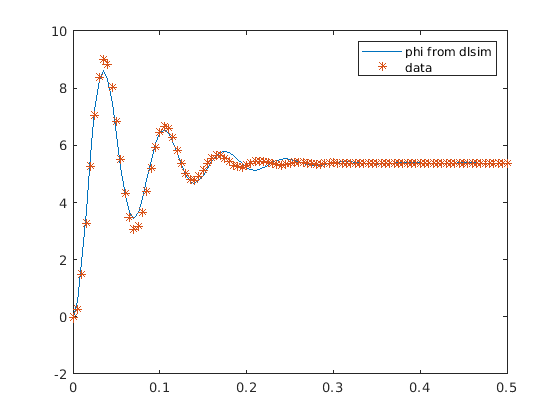

checkStep.numTimeSteps= 100;
checkStep.t= (0:checkStep.numTimeSteps-1)* delta_t;
checkStep.uStep= 5; % deg
checkStep.u= checkStep.uStep* ones(1, checkStep.numTimeSteps);
checkStep.initConds= [0 0];
[~, checkStep.x]= dlsim(sysd.A, sysd.B, sysd.C, sysd.D, checkStep.u, checkStep.initConds);
figure();
plot(checkStep.t(1,:), checkStep.x(:, 1), '-');
hold on;
plot(shifted_tData, shifted_yDeg, '*');
legend('phi from dlsim', 'data');
hold off;

#### Set up open-loop system with integrator

See the files in the Notes directory for an explanation.

sysDiscreteOpen.Abar= [Ad(1,1) Ad(1,2) 0;
    Ad(2,1) Ad(2,2) 0;
    -1 0 1]; 
sysDiscreteOpen.bbar= [Bd(1,1); 
    Bd(2,1);
    0]; 
sysDiscreteOpen.br= [0; 0; 1];
sysDiscreteOpen.cT= [1 0 0];

Simultate new open-loop system with additional integrator state and compare to measured data again.

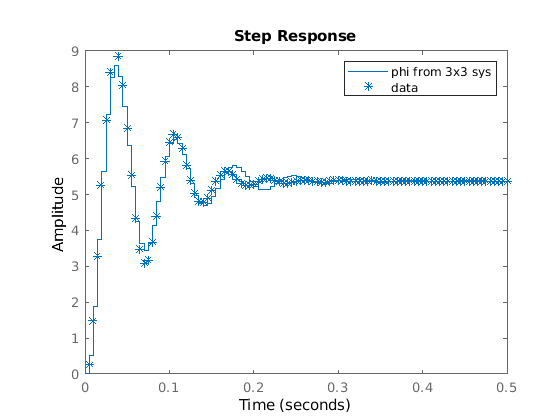

figure();
stepOpt = stepDataOptions('StepAmplitude', checkStep.uStep);
step(ss(sysDiscreteOpen.Abar, sysDiscreteOpen.bbar, sysDiscreteOpen.cT, 0, delta_t), stepOpt); 
hold on;
plot(shifted_tData, shifted_yDeg, '*');
legend('phi from 3x3 sys', 'data');
hold off;

#### Close loop for system with integrator with state feedback

Set desired poles in continuous time and convert them to discrete time.

% continuousTimePoles= [-51, -50, -53];
continuousTimePoles= [-101, -100, -102];
discreteTimePoles= continuousTimePoleToDiscrete(continuousTimePoles, delta_t); 

sysDiscreteOpen.kbarT= place(sysDiscreteOpen.Abar, sysDiscreteOpen.bbar, discreteTimePoles); 

Create closed-loop system.

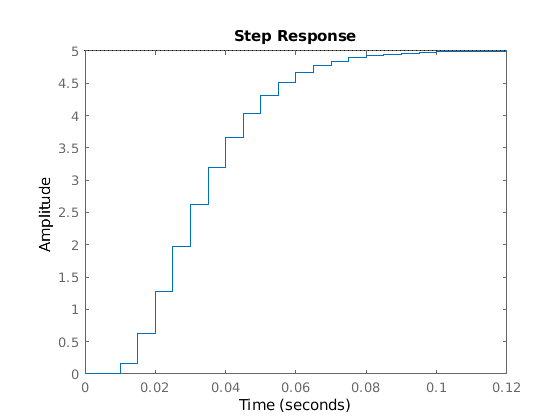

sysDiscreteClosed= ss(sysDiscreteOpen.Abar- sysDiscreteOpen.bbar* sysDiscreteOpen.kbarT, ...
    sysDiscreteOpen.br, sysDiscreteOpen.cT, 0, delta_t);
figure();
stepOpt = stepDataOptions('StepAmplitude', checkStep.uStep);
step(sysDiscreteClosed, stepOpt); 

## Auxiliary functions

Functions defined here at the end of the live-script can be called in the live-script above.

function z= continuousTimePoleToDiscrete(s, Ts)
%CONTINUOUSTIMEPOLETODISCRETE Applies inverse bilinear transformation to s. 
% Converts pole s (or any other point in C) to discrete time pole with
% bilinear transformation, where Ts is the sampling time.

% if more than one pole is given in s, loop over all of them
numPoles= length(s);
if numPoles==1
    z= (2+s*Ts)/(2-s*Ts);
else
    z= zeros(1, numPoles); % allocate to avoid dynamic allocation
    for k= 1:numPoles 
        z(k)= continuousTimePoleToDiscrete(s(k), Ts);
    end
end

end